# TITLE: Signal Modulation and Detection in an AWGN Channel

Authors: Fernando Guiomar [guiomar@av.it.pt](guiomar@av.it.pt) 

Last Update: 08/11/2019

## Initialization

clear;
clear global;
close all;
clc;

% Load Libraries:
addpath(genpath('..\..\..\'));

global PROG;
PROG.showMessagesLevel = 2;
initProg();

Current Date: 10-Nov-2019 01:17:21


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                      PROGRAM INITIALIZATION                      %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


RGB = fancyColors();

## Input Parameters

SIG.M = 16;                 % QAM constellation size
SIG.symRate = 60e9;         % total symbol-rate of the signal
SIG.modulation = 'QAM';     % modulation type [QAM/PAM]
SIG.rollOff = 0.1;          % roll-off factor
SIG.nPol = 1;               % number of polarizations
SIG.nSyms = 2^18;           % total number of simulated symbols
nSpS = 2;                   % number of samples per symbol

SNR_dB = 15;                % SNR in dB

## Set Transmitter Parameters

#### Signal Parameters:

TX.SIG = setSignalParams('symRate',SIG.symRate,'M',SIG.M,...
    'nPol',SIG.nPol,'nBpS',log2(SIG.M),'nSyms',SIG.nSyms,...
    'roll-off',SIG.rollOff,'modulation',SIG.modulation);

#### Modulation Parameters:

TX.QAM = QAM_config(TX.SIG);

#### Bit Parameters:

TX.BIT.source = 'randi';
TX.BIT.seed = 1;

#### Pulse Shaping Filter Parameters:

TX.PS.type = 'RRC';
TX.PS.rollOff = TX.SIG.rollOff;
TX.PS.nTaps = 128;

#### DAC Parameters:

TX.DAC.RESAMP.sampRate = nSpS*TX.SIG.symRate;

#### Matched-Filter Parameters:

MF.type = 'RRC';
MF.rollOff = TX.SIG.rollOff;

## Generate Tx Bits

TX.BIT.txBits = Tx_generateBits(SIG.nSyms,TX.QAM.M,TX.QAM.nPol,TX.BIT);

## Generate Transmitted Symbols

[S.tx,TX.BIT.txSyms] = Tx_QAM(TX.QAM,TX.BIT.txBits);

#### Plot Transmitted Constellation Symbols:

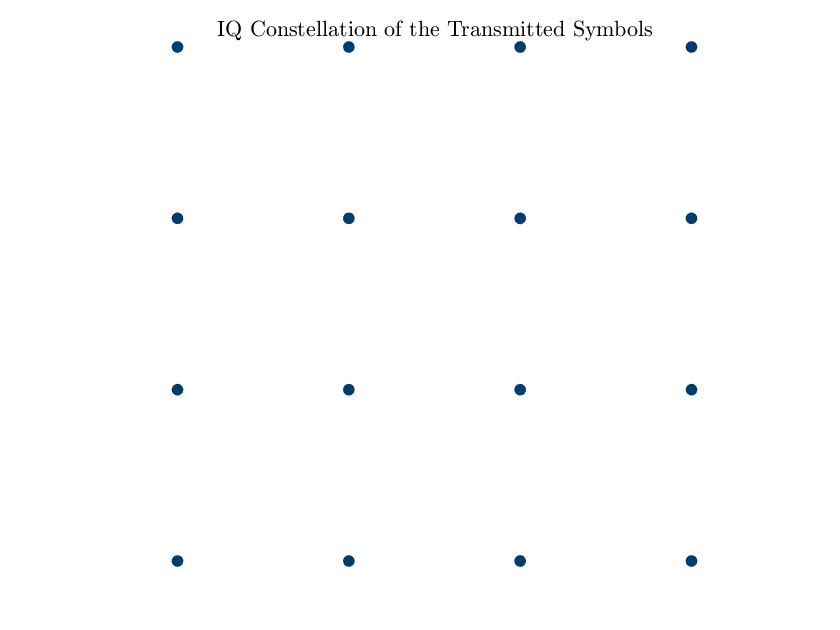

scatterPlot(S.tx,'markersize:sig',20);
title('IQ Constellation of the Transmitted Symbols','interp','latex')

## Pulse Shaping

[S.txSC,TX.PS] = pulseShaper(S.tx,nSpS,TX.PS);

#### Plot Pulse Shaping Taps:

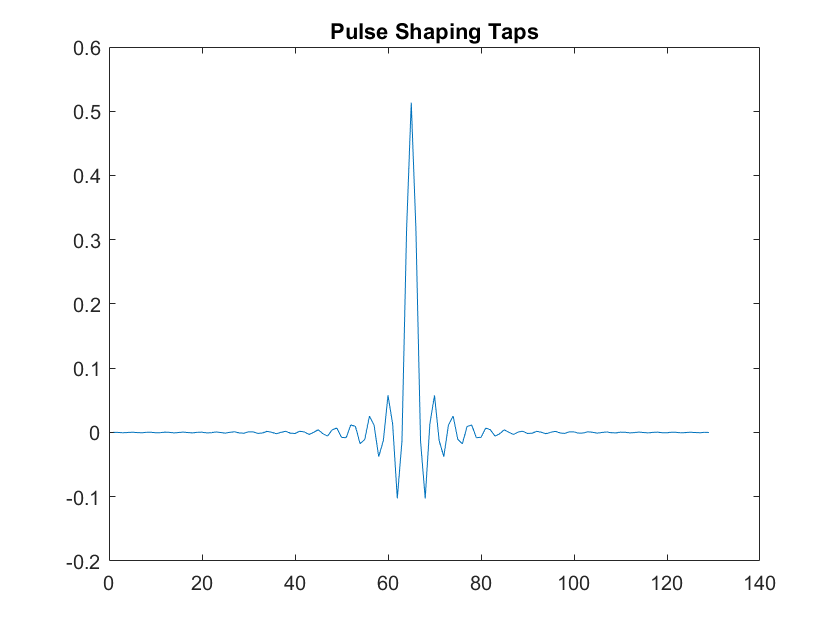

figure();
plot(TX.PS.W);
title('Pulse Shaping Taps')

#### Plot Signal Spectrum:

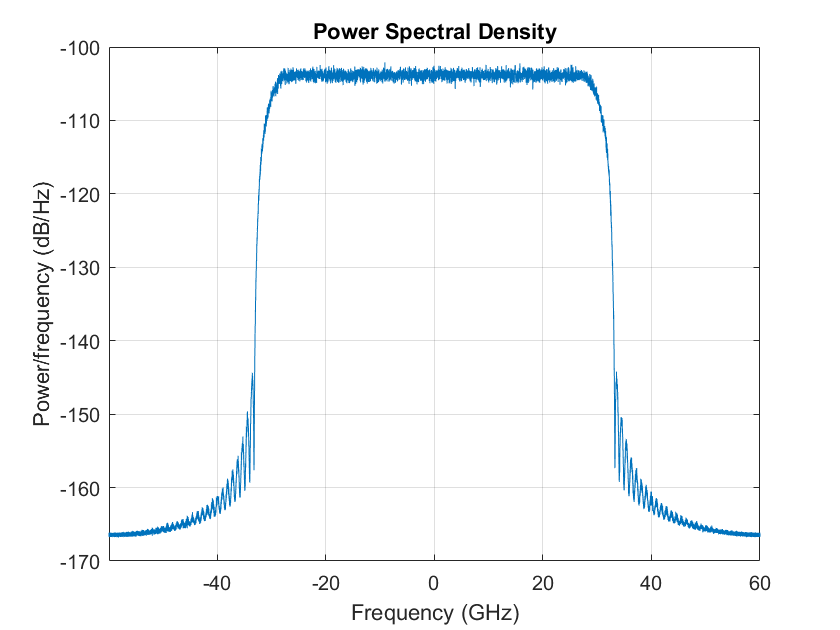

figure();
pwelch(S.txSC(1,:),1e4,[],[],TX.DAC.RESAMP.sampRate,'centered')

## Set SNR

S.rx = setSNR(S.txSC,SNR_dB,TX.DAC.RESAMP.sampRate,SIG.symRate);

#### Plot Received Constellation Symbols

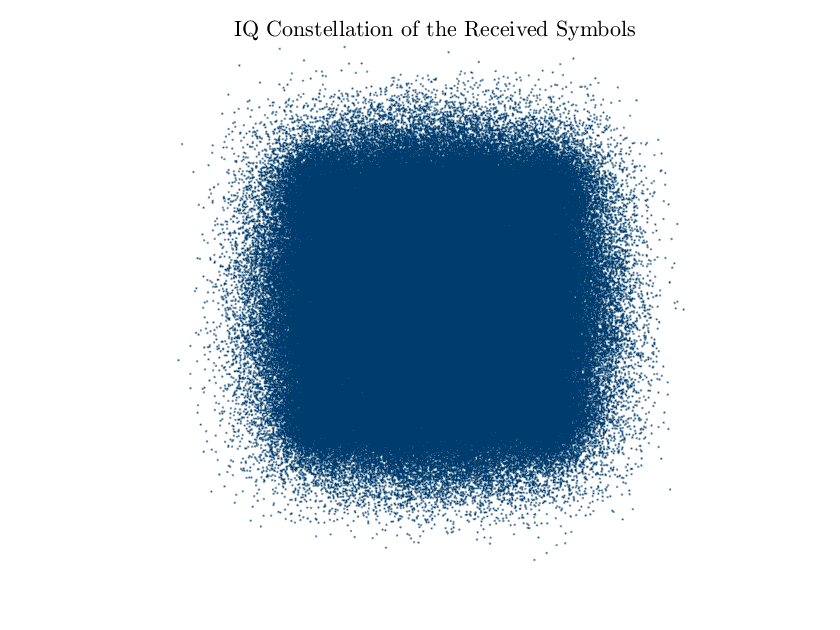

scatterPlot(S.rx);
title('IQ Constellation of the Received Symbols','interp','latex')

#### Plot Received Signal Spectrum

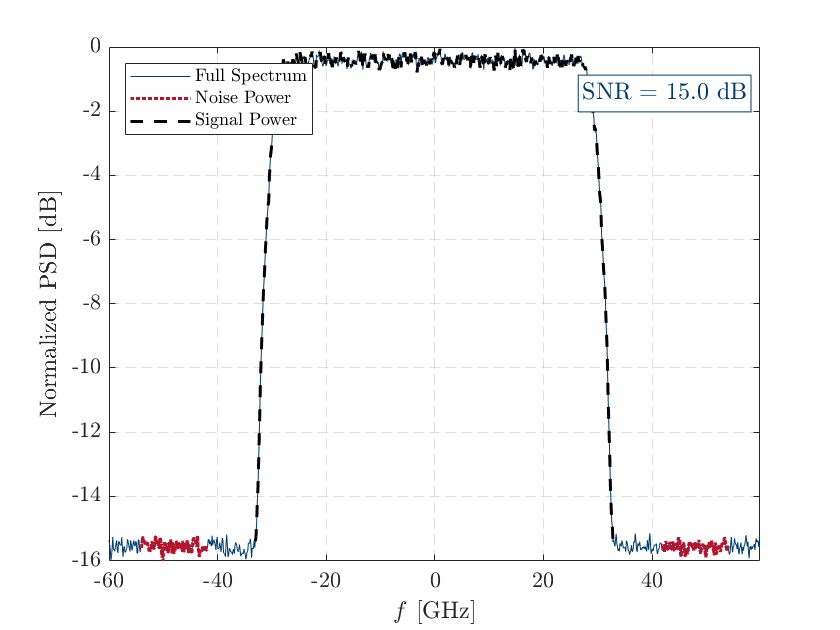

Fs = TX.DAC.RESAMP.sampRate;
Sf = pwelch(S.rx,1e3,[],[],Fs,'centered','psd').';
[SNR_rx_dB,Ps,Pn] = SNR_estimateFromSpectrum(Sf,Fs,TX.SIG.symRate,...
    TX.SIG.rollOff,[-0.9 -0.7; 0.7 0.9],0,true);

## Apply Matched Filter

S.rx = LPF_apply(S.rx,MF,TX.DAC.RESAMP.sampRate,SIG.symRate);

## Downsample to 1 Sample/Symbol

S.rx_1sps = S.rx(1:nSpS:end);

## Apply Symbol Demapper

C = TX.QAM.IQmap;
[DEMAPPER,S.tx] = symDemapper(S.rx_1sps,S.tx,C);

## Calculate Bit-Error Ratio (BER)

[BER,errPos] = BER_eval(DEMAPPER.txBits,DEMAPPER.rxBits);

## Calculate Error Vector Magnitude (EVM)

EVM = EVM_eval(S.rx_1sps,S.tx);

## Plot Constellation after Demapping

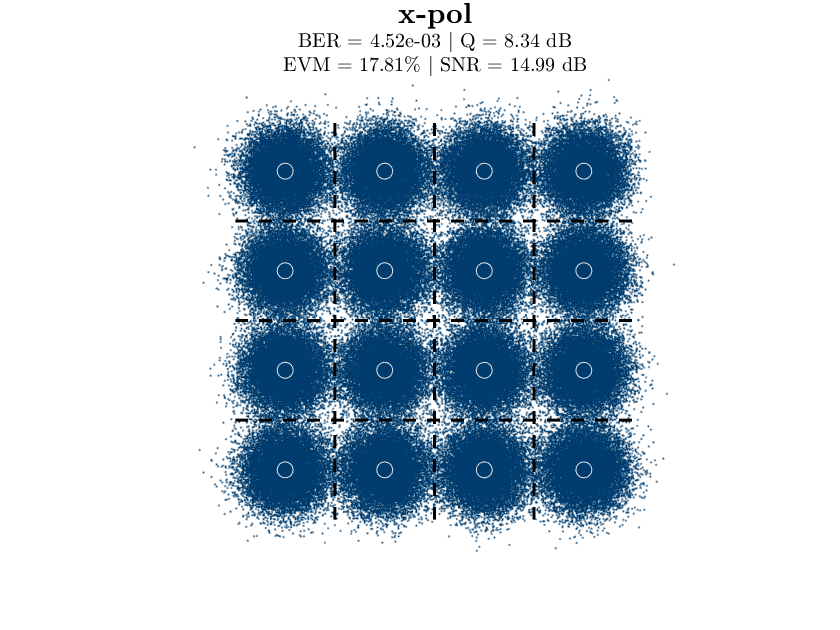

scatterPlot(S.rx_1sps,'BER',BER,'EVM',EVM,'const',DEMAPPER.C);

% title('IQ Constellation of the Received Symbols After Demapper')

## Exit PROG

exitProg();



Total Elapsed Time: 11.8487 [s]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                               END                                %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
